# pyDES - A Performance Modeling Showcase

Giacomo Marciani

Department of Civil and Computer Engineering

University of Rome Tor Vergata

[gmarciani@acm.org](mailto:gmarciani@acm.org)

## `Abstract`

`This script visualizes the performance evaluation of the system proposed in [1]. The dataset is generated by the experiements implememted in [2].`

`This script allows to conduct the following studies:`

- `randomness``: the custom pseudo-random number generator is evaliuated in comparison with a past e present de-facto standard;`

- `transient analysis``: the transient period of the proposed system is evaluated taking into account the convergence of response time, throughput and mean population;`

- `performance evaluation``: the performance metrics of the proposed system are evaluated. In particular we assess response time, throughput, mean population, switched ratio and switched response time both classed/global and system/subsystems.`

`This work is inteded as a final test for the course in Performance Modeling of Computer Systems and Networks[7,8,9].`

## `Pseudo-Random Number Generation`

`Let us evaluate the pseudo-random number generator, defined by the following parameters, assessing its randomness with the Spectral Test[?], the Test of Extremes[?] and the Kolmogorov-Smirnov Analysis[?].`

modulus = 2147483647;
multipliers = [50812, 48271, 16807];

`Spectral Test`

`Let us see the results obtained with the Spectral Test.`

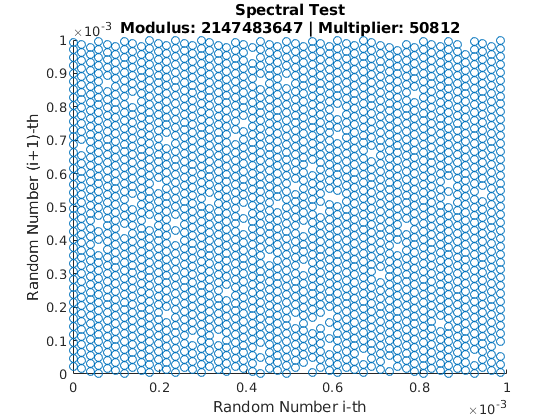

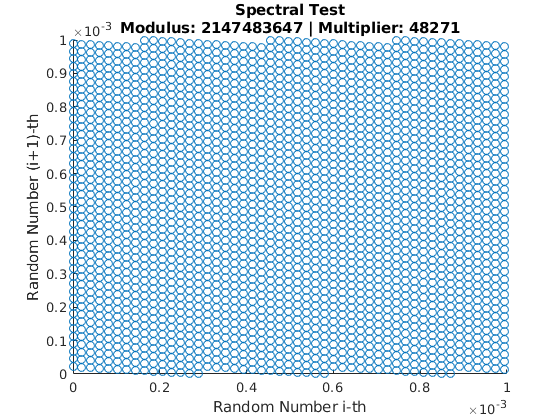

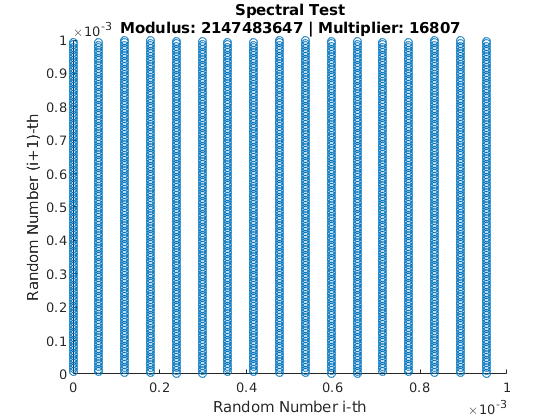

for multiplier = multipliers
    data = readtable(sprintf("random/randomness/out/spectral/mod%d_mul%d.csv", modulus, multiplier));
    
    x = data.u1;
    y = data.u2;
    
    scatter(x, y);
    title({"Spectral Test";sprintf("Modulus: %d | Multiplier: %d", modulus, multiplier)});
    xlabel("Random Number i-th");
    ylabel("Random Number (i+1)-th");
    figure;
end

`Test of Extremes`

`Let us see the results obtained with the Test of Extremes.`

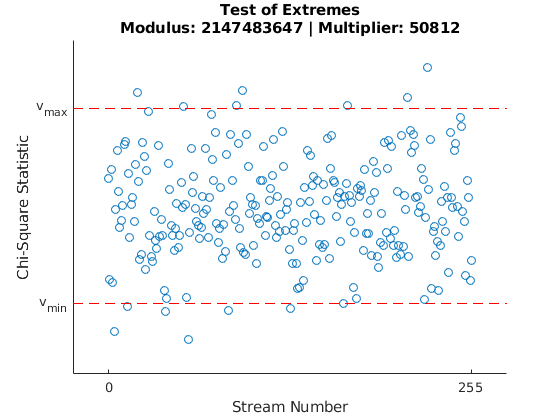

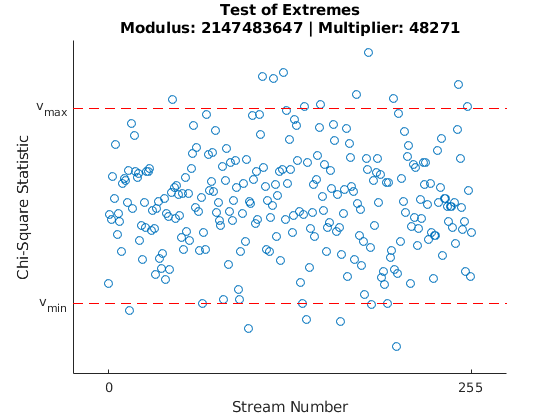

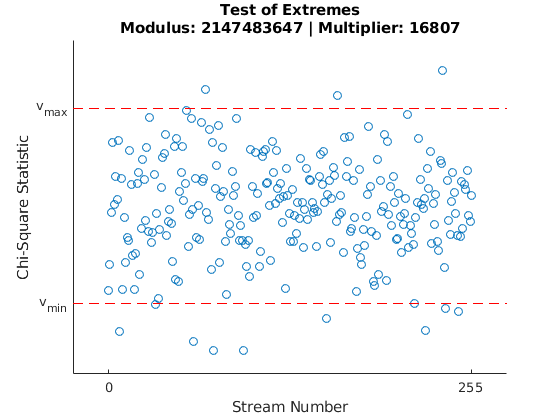

for multiplier = multipliers
    data = readtable(sprintf('random/randomness/out/extremes/mod%d_mul%d.csv', modulus, multiplier));
    report = readtable(sprintf('random/randomness/out/extremes/mod%d_mul%d_report.csv', modulus, multiplier));
    
    x = data.stream;
    y = data.value;
    
    criticalLower = report.critical_bounds_lower_bound;
    criticalUpper = report.critical_bounds_upper_bound;
    
    streams = length(x);
    offset = 25;
    
    scatter(x, y);
    hold on
    plot([-offset streams-1+offset], [1 1] * criticalLower, '--r')
    plot([-offset streams-1+offset], [1 1] * criticalUpper, '--r')
    hold off
    title({'Test of Extremes';sprintf('Modulus: %d | Multiplier: %d', modulus, multiplier)});
    xlabel('Stream Number');
    ylabel('Chi-Square Statistic');
    xlim([ -offset streams-1+offset ])
    set(gca,'xtick',[0 streams-1]);
    set(gca,'ytick',[criticalLower criticalUpper]);
    yticklabels({'v_{min}', 'v_{max}'});
    figure;
end

`Kolmogorov-Smirnov Analysis`

`Let us see the results obtained with the Kolmogorov-Smirnov Analysis.`

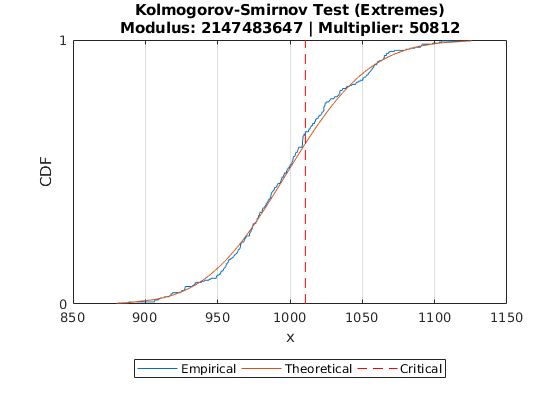

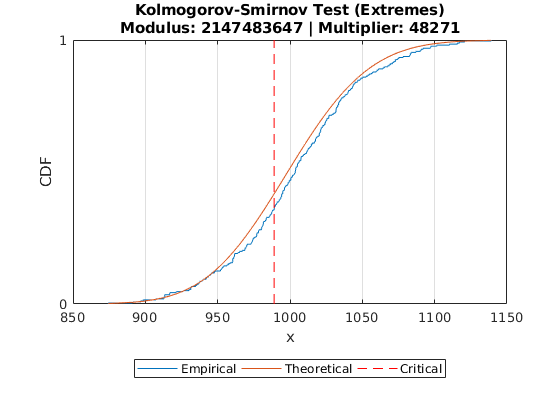

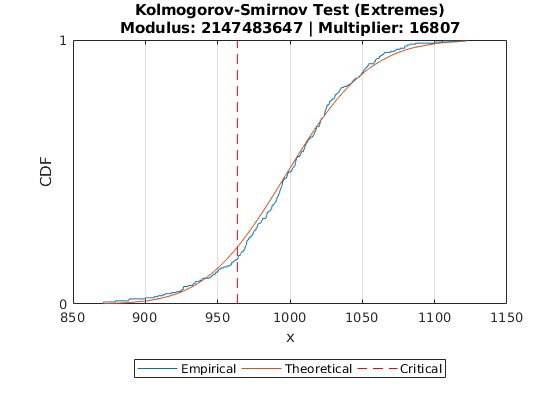

for multiplier = multipliers
    data = readtable(sprintf('random/randomness/out/kolmogorov-smirnov/extremes/mod%d_mul%d.csv', modulus, multiplier));
    report = readtable(sprintf('random/randomness/out/kolmogorov-smirnov/extremes/mod%d_mul%d_report.csv', modulus, multiplier));
    
    bins = report.test_parameters_bins;
    critical = report.ks_ks_point_x;
    
    empirical = sort(data.value);
    theoretical = chi2cdf(empirical, bins - 1);
    
    cdfplot(empirical)
    hold on
    plot(empirical, theoretical)
    plot([1 1] * critical, [0.0 1.0], '--r')
    hold off
    title({'Kolmogorov-Smirnov Test (Extremes)';sprintf('Modulus: %d | Multiplier: %d', modulus, multiplier)});
    xlabel('x');
    ylabel('CDF');
    set(gca,'ytick',[0.0 1.0]);
    legend('Empirical', 'Theoretical', 'Critical', 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `Transient Analysis`

`Let us now study the transient period of the simulated system.`

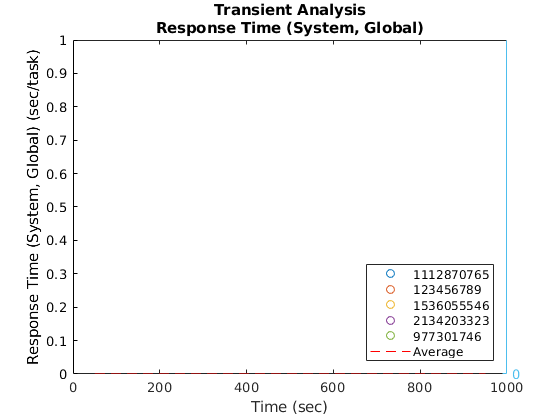

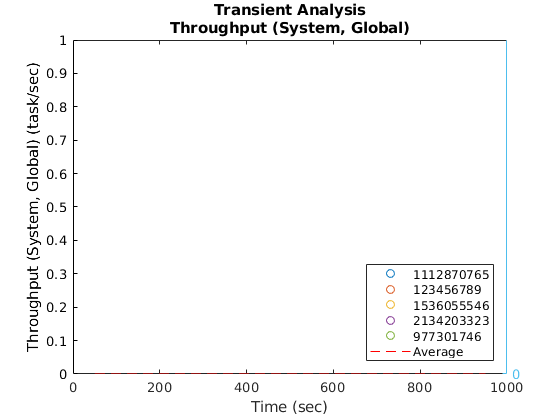

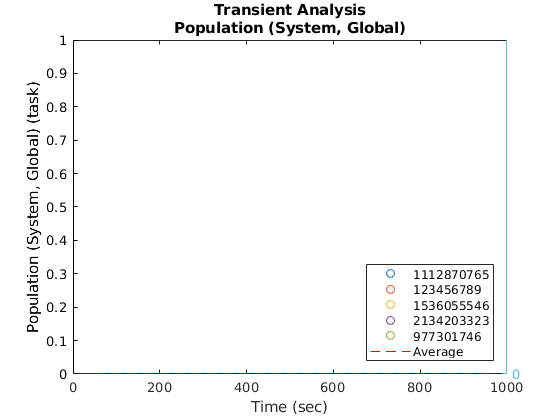

measures = ["Response Time (System, Global)", "Throughput (System, Global)", "Population (System, Global)"];
entries  = ["response_system_global", "throughput_system_global", "population_system_global"];
units    = ["sec/task", "task/sec", "task"];
samplePoints = 30;
ratioForMean = 0.5;

ls = dir('simulation/out/transient_analysis/seed_*');
seeds = strrep(string({ls.name}.'),'seed_','');

for i = 1:length(measures)
    measure = measures(i);
    entry   = entries(i);
    unit    = units(i);
    
    valuesForMean = [];
    
    title({'Transient Analysis', measure});
    xlabel('Time (sec)');
    ylabel(sprintf('%s (%s)', measure, unit));
    
    hold on
    
    for s = 1:length(seeds)
        seed = seeds{s,1};
        data = readtable(sprintf('simulation/out/transient_analysis/seed_%s/result.sampling.csv', seed));
        time = data.time;
        values = data.(char(entry));
        
        nValues = length(time);
        valuesForMean = cat(1, valuesForMean, values(floor(ratioForMean*nValues):1:end));        
        samplePace = floor(nValues/samplePoints);
    
        scatter(time(1:samplePace:end), values(1:samplePace:end), 10, 'LineWidth', 0.1, 'DisplayName', seed);    
    end
    
    hold off
    
    yl = ylim;
    
    avg = mean(valuesForMean);
    
    yyaxis right
    plot(time, ones(size(time)) * avg, '--r', 'DisplayName', 'Average');
    ylim(yl);
    set(gca,'ytick', (avg));
    legend('show', 'Location', 'southeast', 'Orientation', 'vertical');
    figure;
end

## `Performance Evaluation`

`Let us now visualize how performance metrics behave in response to threhsold variations.`

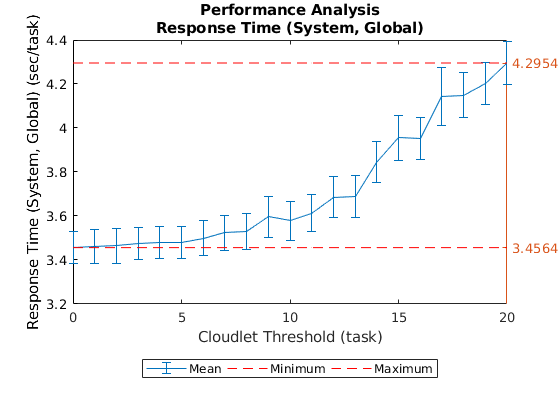

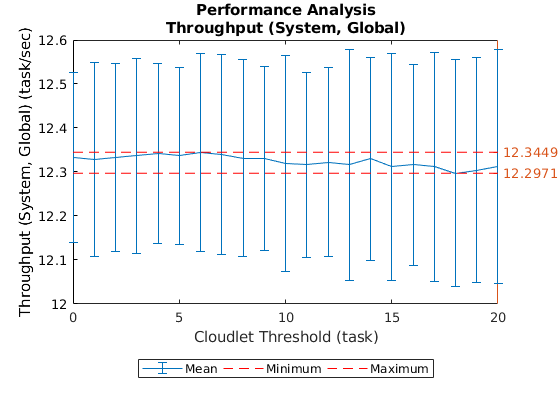

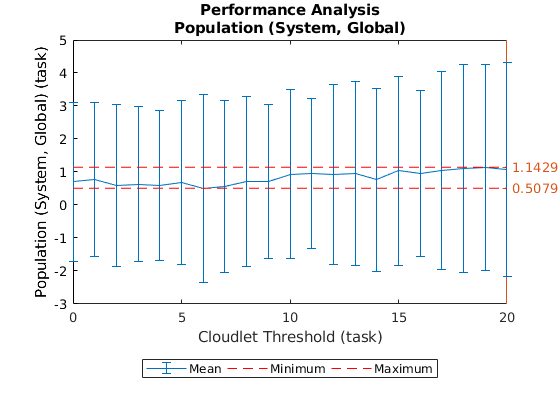

measures = ["Response Time (System, Global)", "Throughput (System, Global)", "Population (System, Global)"];
entries  = ["statistics_response_system_global", "statistics_throughput_system_global", "statistics_population_system_global"];
units    = ["sec/task", "task/sec", "task"];

data = readtable('simulation/out/performance_analysis/result.csv');

thresholds = data.system_cloudlet_threshold;

one = ones(size(thresholds));
for i = 1:length(measures)
    measure = measures(i);
    ventry  = sprintf("%s_mean", entries(i));
    eentry  = sprintf("%s_cint", entries(i));
    unit    = units(i);
    notable = notables(i);
    
    values = data.(char(ventry));
    errors = data.(char(eentry));
    
    mn = min(values);
    mx = max(values);
    
    errorbar(thresholds, values, errors, 'DisplayName', 'Mean');
    title({'Performance Analysis', measure});
    xlabel('Cloudlet Threshold (task)');
    ylabel(sprintf('%s (%s)', measure, unit));
    
    yl = ylim;
    
    yyaxis right
    hold on
    plot(thresholds, ones(size(thresholds)) * mn, '--r', 'DisplayName', 'Minimum');
    plot(thresholds, ones(size(thresholds)) * mx, '--r', 'DisplayName', 'Maximum');
    hold off
    ylim(yl);
    set(gca,'ytick', [mn, mx]);
    legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end


% SUMMARY
tabularFields = [{'Threshold'} cellstr(regexprep(measures,' |\(|\)|,',''))];
tabularEntries = [{'system_cloudlet_threshold'} cellstr(arrayfun(@(x) strcat(x, "_mean"), entries))];
tabular = data(:,tabularEntries);
tabular.Properties.VariableNames = tabularFields;
disp(tabular);

    Threshold    ResponseTimeSystemGlobal    ThroughputSystemGlobal    PopulationSystemGlobal
    _________    ________________________    ______________________    ______________________

     0           3.4564                      12.333                    0.69841               
     1           3.4615                      12.329                    0.77778               
     2           3.4638                      12.333                     0.5873               
     3           3.4766                      12.337                    0.63492               
     4           3.4783                      12.342                    0.60317               
     5           3.4788                      12.337                    0.68254               
     6           3.4995                      12.345                    0.50794               
     7           

## `Distribution Analysis`

`Let us now study the probability distribution function and the cumulative distribution function of a given metric. Please, notice that the variable ``dists`` should be modified accordingly to the result reported by the Distribution Fitter.`

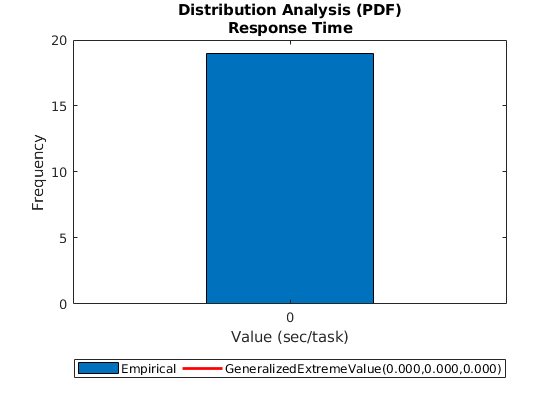

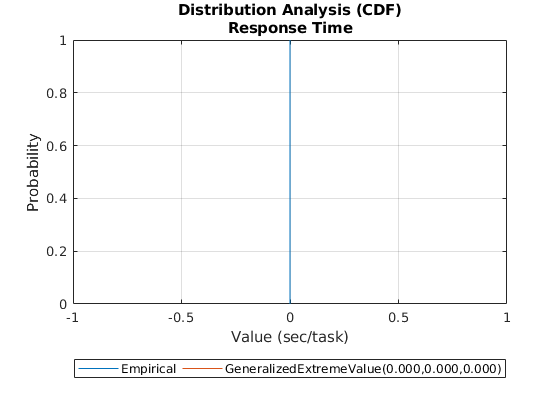

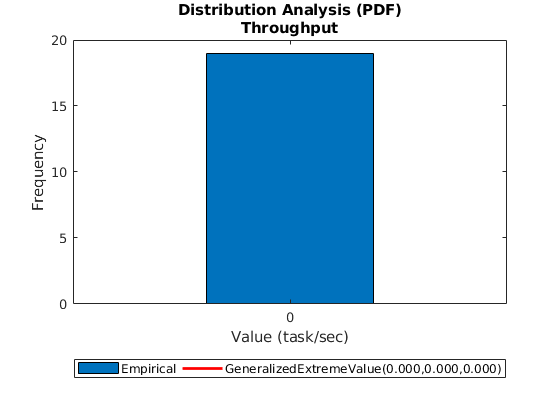

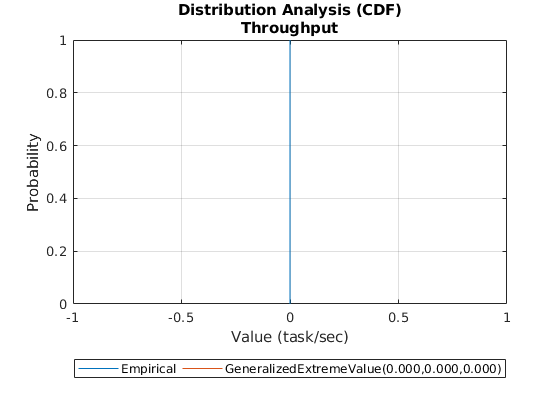

measures = ["Response Time (System, Global)", "Throughput (System, Global)", "Population (System, Global)"];
entries  = ["response_system_global", "throughput_system_global", "population_system_global"];
units    = ["sec/task", "task/sec", "task"];
dists    = ["GeneralizedExtremeValue", "GeneralizedExtremeValue", "GeneralizedExtremeValue"];

S = 20;

data = readtable(sprintf('simulation/out/performance_analysis/%d/result.sampling.csv', S));

for i = 1:length(metrics)
    metric = metrics(i);
    entry = entries(i);
    unit = units(i);
    dist = dists(i);
    
    empirical = sort(data.(char(entry)));
    
    %%
    % PDF
    %%
    bins = size(histcounts(empirical), 2);
    dparams = fitdist(empirical, char(dist));
    histfit(empirical, bins, char(dist));
    title({'Distribution Analysis (PDF)', metric});
    xlabel(sprintf('Value (%s)', unit));
    ylabel('Frequency');
    legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dist, dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
    
    %%
    % CDF
    %%
    cdfplot(empirical);
    cdfTheoretical = cdf(char(dist), empirical, dparams.k, dparams.sigma, dparams.mu);
    hold on
    plot(empirical, cdfTheoretical);
    hold off
    
    title({'Distribution Analysis (CDF)', metric});
    xlabel(sprintf('Value (%s)', unit));
    ylabel('Probability');
    legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dist, dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `References`

- `Relazione, `[`https://www.cryptocompare.com`](https://www.cryptocompare.com)

- `Repo Github, `[`https://www.github.com/gmarciani/pydes`](https://www.cryptocompare.com)

- `Performance Modeling of Computer Systems and Networks, `[`http://didattica.uniroma2.it/informazioni/index/insegnamento/172514-Performance-Modeling-Of-Computer-Systems-And-Networks`](http://didattica.uniroma2.it/informazioni/index/insegnamento/172514-Performance-Modeling-Of-Computer-Systems-And-Networks)

- `Leemis, Lawrence M., and Stephen Keith Park. ``Discrete-event simulation: A first course``. Upper Saddle River, NJ: Pearson Prentice Hall, 2006.`

- `Harchol-Balter, Mor. ``Performance modeling and design of computer systems: queueing theory in action``. Cambridge University Press, 2013.`